# Unsupervised analyses

**Author**: Scott Campit

## Summary

This liverscript goes over unsupervised analyses for shME1 metabolomics. By unsupervised analyses, we really mean algorithms and processing methods that allow us to extract information about the dataset using only the dataset itself, rather than "learning" relationships between two variables.

### Useful resources to reference to:

- Tutorial of hierarchical clustering: [https://www.cs.princeton.edu/courses/archive/fall18/cos324/files/hierarchical-clustering.pdf](https://www.cs.princeton.edu/courses/archive/fall18/cos324/files/hierarchical-clustering.pdf)

## Load the dataset for ME1

This module performs hierarchical clustering on the data

% Read in the data
metabolomicsFile = '~/Data/Expression/Metabolomics/ME1/raw/ME1_Metabolomics.xlsx';
data = readtable(metabolomicsFile, 'Sheet', "TU8902 Intra")

data = 224×27 table
               CompoundMethod                c      e    g     l      m      n     r    x    TU8902ShNT_DoxDay5R1    TU8902ShNT_DoxDay5R2    TU8902ShNT_DoxDay5R3    TU8902ShNT_DoxDay5R1_1    TU8902ShNT_DoxDay5R2_1    TU8902ShNT_DoxDay5R3_1    TU8902ShME1_DoxDay1R1    TU8902ShME1_DoxDay1R2    TU8902ShME1_DoxDay1R3    TU8902ShME1_DoxDay3R1    TU8902ShME1_DoxDay3R2    TU8902ShME1_DoxDay3R3    TU8902ShME1_DoxDay5R1    TU8902ShME1_DoxDay5R2    TU8902ShME1_DoxDay5R3    TU8902ShME1_DoxDay5R1_1    TU8902ShME1_DoxDay5R2_1    TU8902Sh

Next, let's just consider raw data values, without the "learning" part. 

We can simply look at how different each metabolite value is from each value for each given condition and time point. This will tell us something about the similarity of our data. We need to construct a distance matrix for each time point and sample. For our purposes, I will only show one time point/condition. 

## Covariance Matrix

Recall that the covariance matrix for a vector is the following: 


$$\mathrm{cov}\left\lbrack X,X\right\rbrack =E\left\lbrack \left(X-\mu_X \right){\left(X-\mu_X \right)}^T \right\rbrack =E\left\lbrack {\mathrm{XX}}^T \right\rbrack -\mu_X \mu_X^T$$


To construct a distance matrix, we can do this either by computing euclidean distances or correlations. I will do this using euclidean distances, because the interpretation will be simple: the closer two observations are, the less dissimilar they are.

### **Some useful properties of the covariance matrix:**

- We can compute a correlation matrix using the covariance matrix

- Diagonals are the variances of the components in the original data

- Off-diagonals are the covariance between pairs of components in the original data

- The covariance is a positive semidefinite and symmetric matrix

### Constructing the covariance matrix

Let's now construct the covariance matrix for one condition and time point: Day 1 shME1 +Dox in TU8902.

% Take the mean
shME1_Dox_1 = mean(table2array(...
                         data(:, ["TU8902ShME1_DoxDay1R1", ...
                                  "TU8902ShME1_DoxDay1R2", ...
                                  "TU8902ShME1_DoxDay1R3"])), 2);

% Find NaNs and assign to 0
shME1_Dox_1(isnan(shME1_Dox_1)) = 0;
                              
% Compute the mean
mu = mean(shME1_Dox_1);

% Compute the distance matrix, which is the covariance matrix.
E = shME1_Dox_1 - mu;
D = E .* E';

### Visualizing the covariance matrix

Now let's visualize the covariance matrix using a heatmap.

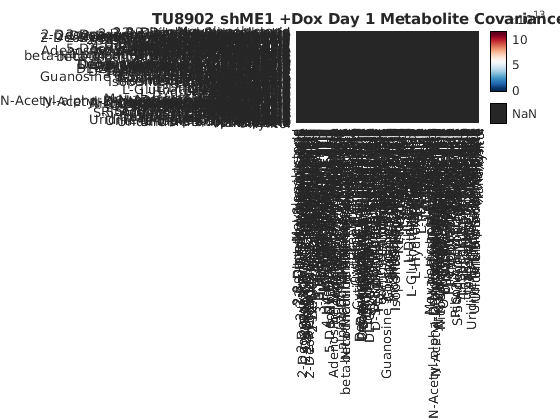

% Visualize the covariance matrix
metabolites = string(table2array(data(:, 'CompoundMethod')));
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);
tmp = tril(D);
tmp(tmp==0) = NaN;
heatmap(tmp, ...
        'XData', metabolites, ...
        'YData', metabolites, ...
        'Colormap', redbluecmap, ...
        'Title', "TU8902 shME1 +Dox Day 1 Metabolite Covariance Matrix")

**Check in:**

- What is the intuition for constructing the covariance matrix (what is it telling us?)

- What are some useful properties for constructing a covariance matrix?

- What are pros and cons of constructing the covariance matrices

## Hierarchical Clustering

This is useful, in that we already see differences in the matrix for specific metabolite pairs. But now, what if we wanted to group metabolites based on these dissimilarity profiles? We can use something called **hierarchical clustering**.

**The goal of hierarchical or agglomerative clustering is to minimize the distance between similar profiles (or clusters), while maximizing the distance between dissimilar clusters, in both the row and column space.** 

The way we do this is by the following algorithm:

- Compute a dissimilarity matrix

- Merge the two closest datapoints

- Update the dissimilarity matrix

- Repeat until a single cluster remains

- Maximize intercluster distance

### Advantages and disadvantages of clustering

Some advantages of hierarchical clustering is that it gives a family of possible solutions, and in many cases, results in meaningful data. However, there is no optimization criterion, and there are different ways of measuring distances that give different results.

### **Ways to compute cluster distances**

**Single linkage**: merge groups based on the shortest distance over all possible pairs:


$$D_{\mathrm{single}} =\underset{n,m}{\mathrm{min}} ||x_n -y_m ||$$


- Strengths include that it can handle diverse distributions of data. 

- Weaknesses are that this metric is sensitive to noise.

**Complete linkage**: merge groups based on the largest distance over all possible pairs


$$D_{\mathrm{complete}} =\underset{n,m}{\mathrm{max}} \left|\right|x_n -y_m \left|\right|$$


- Strengths include that it is robust to noise.

- Weaknesses include that it tends to break towards large, spherical clusters.

**Average linkage**: merge groupos based on the average distance across all possible pairs.


$$D_{\mathrm{average}} =\underset{n,m}{\mathrm{mean}} \left|\right|x_n -y_m \left|\right|$$


- Strengths are that it is less susceptible to noise than single linakge.

- Weaknesses are that it is still biased for spherical clusters.

### Applying agglomerative clustergrams in MATLAB

First, let's load all the data into a single matrix called tmp2. We'll include replicates to illustrate a point about hierarchical clustering.

tmp2 = table2array(data(:, 10:end))

tmp2 = 	1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2387    0.2463    0.2374    0.1464    0.1816    0.1728    0.1352    0.1739    0.1715    0.1584    0.1569    0.1595    0.1540    0.1686    0.1434    0.2098    0.2181    0.2001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0009    0.0009    0.0010    0.0008    0.0011    0.0012    0.0010    0.0014    0.0013    0.0014    0.0012    0.0012    0.0021    0.0018    0.0020    0.0011    0.0012    0.0011
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.

We'll set NaN data to 0.

tmp2(isnan(tmp2)) = 0;

Finally, let's prettify our labels.

conditions = data.Properties.VariableNames(10:end);
conditions = strrep(conditions, "_", " ")

conditions = 1×18 string array
  Columns 1 through 3

    "TU8902ShNT DoxDay…"    "TU8902ShNT DoxDay…"    "TU8902ShNT DoxDay…"

  Columns 4 through 6

    "TU8902ShNT DoxDay…"    "TU8902ShNT DoxDay…"    "TU8902ShNT DoxDay…"

  Columns 7 through 9

    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"

  Columns 10 through 12

    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"

  Columns 13 through 15

    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"

  Columns 16 through 18

    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"    "TU8902ShME1 DoxDa…"


The bottom code computes the clustergram using the euclidean distances for both metabolites and conditions.

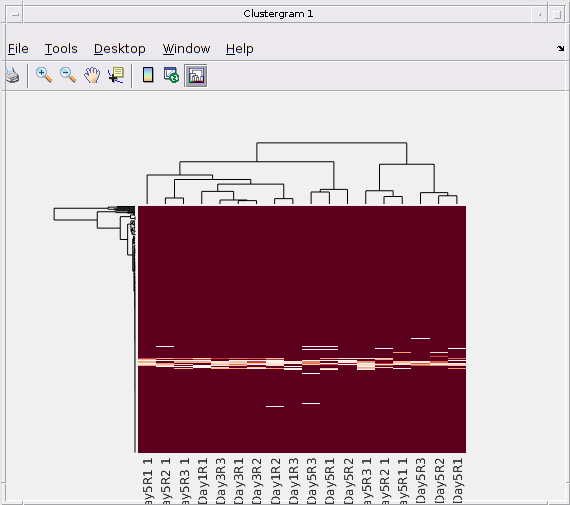

Clustergram object with 224 rows of nodes and 18 columns of nodes.



clustergram(tmp2, ...
        'RowLabels', metabolites, ...
        'ColumnLabels', conditions, ...
        'RowPdist', 'euclidean', ...
        'ColumnPdist', 'euclidean', ...
        'Colormap', redbluecmap)

**Check in**:

- How would you interpret the metabolite clusters?

- How would you interpret the condition clusters?